## -- Hydrological Modeling Team --

## Developed by H2O  - KMITL

This code is being used in the competition at TESA TOPGUN Rally 2023.

อ่านข้อมูลจาก dataset

clear
clc
data = readmatrix("dataset-2a.xlsx", 'Sheet','Q1A');
qh1 = readmatrix("dataset-2a.xlsx", 'Sheet','QH_S1');
qh3 = readmatrix("dataset-2a.xlsx", 'Sheet','QH_S3');

เก็บข้อมูลลงตัวแปร

hs1 = data(1:55,2);
qs1 = data(1:55,3);
qs2 = data(1:60,4);
qs3 = data(1:60,5);

นำข้อมูล H D56-60 ที่สถานี S1 เข้าจาก Server

api = 'http://192.168.1.59:80/water/heights';
url = api;
raw = webread(url)

raw = struct with fields:
       data: [1×5 struct]
        len: 5
    message: 'gets data'


heighttable = struct2table(raw.data);
heighttable = heighttable(:,3);
height = table2array(heighttable);
%h56_60 = magic(raw);
h56_60 = height;

hs1 = [hs1;h56_60];

คำนวณ Q56-60 จาก H56-60 ของ S1 

% Read data from Excel file
xdata = readmatrix("dataset-2a.xlsx", 'Sheet', 'Q1A');
ydata = readmatrix("dataset-2a.xlsx", 'Sheet', 'Q1A');

% Flatten and clean x_data
xdata = xdata(:, 3);
clr_x = rmmissing(xdata(:));

% Flatten and clean y_data
ydata = ydata(:, 2);
clr_y = rmmissing(ydata(:));

% Data
y = clr_x;
x = clr_y;

% Fit quadratic polynomial regression model
polyModel = fitlm(x, y, 'poly2');

% Display the coefficients
coefficients = polyModel.Coefficients.Estimate;
intercept = coefficients(1);
linear_coeff = coefficients(2);
quadratic_coeff = coefficients(3);

fprintf('Fitted coefficients: intercept = %.4f, linear_coeff = %.4f, quadratic_coeff = %.4f\n', intercept, linear_coeff, quadratic_coeff);

Fitted coefficients: intercept = 18872.9828, linear_coeff = -520.3876, quadratic_coeff = 3.1816


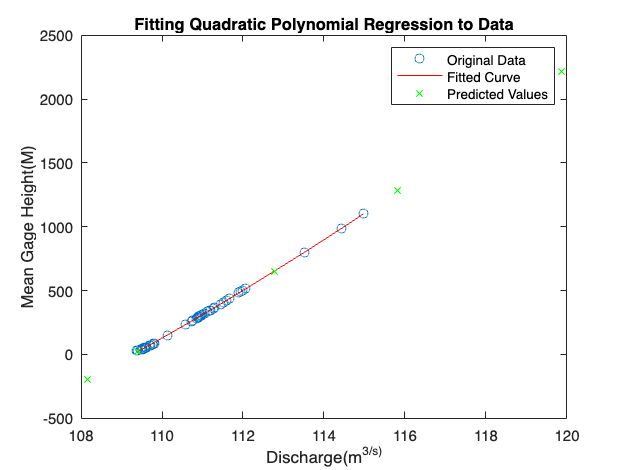


% Plot the original data, the fitted curve, and the predicted values
figure;
plot(x, y, 'o', 'DisplayName', 'Original Data');
hold on;
fittedCurve = intercept + linear_coeff * x + quadratic_coeff * x.^2;
plot(x, fittedCurve, 'r-', 'DisplayName', 'Fitted Curve');

% Input new values of x for prediction
new_y = h56_60;
predicted_x = predict(polyModel, new_y);
predicted_x = round(predicted_x, 2);
q56_60 = predicted_x;
qs1 = [qs1;q56_60];

% Plot the predicted values
plot(new_y, predicted_x, 'gx', 'DisplayName', 'Predicted Values');
hold off;

legend('show');
xlabel('Discharge(m^3/s)');
ylabel('Mean Gage Height(M)');
title('Fitting Quadratic Polynomial Regression to Data');


% Calculate R squared
R_squared = polyModel.Rsquared.Ordinary;

% Mean Absolute Error (MAE) calculation
MAE = mean(abs(y - fittedCurve));

% Mean Squared Error (MSE) calculation
MSE = sum((y - fittedCurve).^2)/numel(y);

fprintf('R squared: %.4f\n', R_squared);

R squared: 0.9999


fprintf('Mean Absolute Error (MAE): %.4f\n', MAE);

Mean Absolute Error (MAE): 1.7998


fprintf('Mean Squared Error (MSE): %.4f\n', MSE);

Mean Squared Error (MSE): 7.7764



% Display the predicted values
fprintf('Q56 - Q60: %.4f, %.4f, %.4f, %.4f, %.4f\n', predicted_x);

Q56 - Q60: 21.5000, -193.2200, 649.9200, 1283.1400, 2212.8300


คำนวณหา Q ของ S3 จาก S1,S2

qsum = qs1+qs2

qsum = 1.0e+03 *

    0.1125
    0.1570
    0.1916
    0.2232
    0.2412
    0.2744
    0.3126
    0.3405
    0.3646
    0.3715


คำนวณหา factor จากความต่างของ QS3 ข้อมูลจริงและที่ได้จากการคำนวณ

f = qs3 - qsum

f = 1.0e+03 *

    0.2795
    0.3590
    0.4004
    0.4828
    0.5487
    0.5076
    0.4574
    0.4255
    0.3934
    0.3705


จากค่า f แต่ละตัวที่ได้มาจากการคำนวณของค่า q จากสถานี S1, S2 และ S3 มารวมกัน 

หากค่า f มีค่าเป็นบวกแสดงว่าในวันนั้นมีน้ำเพิ่มขึ้น 

หากเป็นลบแสดงว่าในวันนั้นมีน้ำลดลง

คำนวณหา H ของ S3

% Read data from Excel file
%data = readmatrix("dataset-2a.xlsx", 'Sheet', 'QH_S3');

% Flatten and clean x_data
dataX = qh3(:,2);
clr_x = rmmissing(dataX(:));

% Flatten and clean y_data
dataY = qh3(:,1);
clr_y = rmmissing(dataY(:));

% Data
x = clr_x;
y = clr_y;

% Fit quadratic polynomial regression model
polyModel = fitlm(x, y, 'poly2');

% Display the coefficients
coefficients = polyModel.Coefficients.Estimate;
intercept = coefficients(1);
linear_coeff = coefficients(2);
quadratic_coeff = coefficients(3);

fprintf('Fitted coefficients: intercept = %.4f, linear_coeff = %.4f, quadratic_coeff = %.4f\n', intercept, linear_coeff, quadratic_coeff);

Fitted coefficients: intercept = 106.7923, linear_coeff = 0.0030, quadratic_coeff = -0.0000


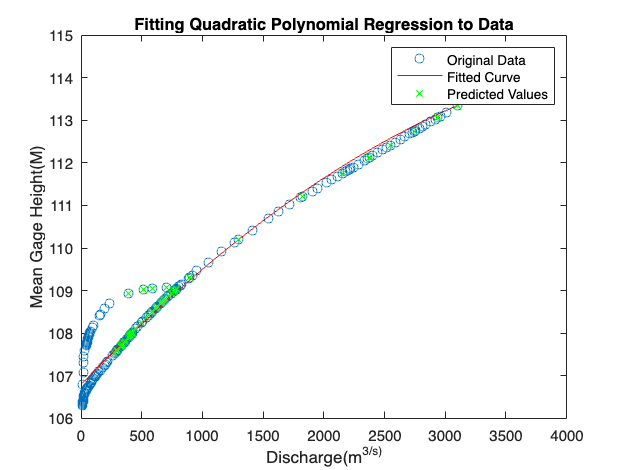


% Plot the original data, the fitted curve, and the predicted values
figure;
plot(x, y, 'o', 'DisplayName', 'Original Data');
hold on;
fittedCurve = intercept + linear_coeff * x + quadratic_coeff * x.^2;
plot(x, fittedCurve, 'r-', 'DisplayName', 'Fitted Curve');

% Input new values of x for prediction
new_x = readmatrix("dataset-2a.xlsx",'Sheet','Q1A');
new_x = new_x(:,5);
new_x = rmmissing(new_x);
qs3 = new_x;
for i = 1:length(new_x)
    if sum(sum(qh3==qs3(i))) > 0
        [row, col] = find(qh3 == qs3(i));
        predicted_y(i) = qh3(row(1),1);
 
    else
        predicted_y = predict(polyModel, new_x);
        predicted_y = round(predicted_y, 2);

    end
end

predicted_y = predicted_y';
hs3 = predicted_y;
% Plot the predicted values
plot(new_x, predicted_y, 'gx', 'DisplayName', 'Predicted Values');
hold off;


legend('show');
xlabel('Discharge(m^3/s)');
ylabel('Mean Gage Height(M)');
title('Fitting Quadratic Polynomial Regression to Data');


% Calculate R squared
R_squared = polyModel.Rsquared.Ordinary;

% Mean Absolute Error (MAE) calculation
MAE = mean(abs(y - fittedCurve));

% Mean Squared Error (MSE) calculation
MSE = sum((y - fittedCurve).^2)/numel(y);

fprintf('R squared: %.4f\n', R_squared);

R squared: 0.9582


fprintf('Mean Absolute Error (MAE): %.4f\n', MAE);

Mean Absolute Error (MAE): 0.3413


fprintf('Mean Squared Error (MSE): %.4f\n', MSE);

Mean Squared Error (MSE): 0.2063


%disp(predicted_y)


ส่งค่า H ของ S3 กลับไปที่ Server

% Define the API endpoint for POST request
postapi = 'http://192.168.1.59:80/water/addHS3';

for i = 1:60
    postData = struct('height', hs3(i),'Day',i, 'discharge', qs3(i));
    postResponse = webwrite(postapi, postData);
end

พยากรณ์ค่า H D61-65 ของสถานี S1


% Read data from Excel file
%dataTable = readmatrix("dataset-2a.xlsx", 'Sheet', 'Q1A');

% Extract and clean data
dataX = 1:60;
dataY = hs1;

% Since dataX is just a sequence from 1 to 50, you can directly use it
x = dataX;
y = dataY;

% Create a neural network model
net = feedforwardnet([20, 15, 10, 5]);

% Prepare data for neural network training
inputs = x;
targets = y';

% Split data into training and testing sets
[trainInd, ~, testInd] = dividerand(length(inputs), 0.8, 0, 0.2);
trainInputs = inputs(trainInd);
trainTargets = targets(trainInd);
testInputs = inputs(testInd);
testTargets = targets(testInd);

% Train the neural network
net = train(net, trainInputs, trainTargets);


% Use the trained neural network to predict on the test set
predicted_y_test = net(testInputs);

% Compute R-squared for the test set
R_squared_test = 1 - sum((testTargets - predicted_y_test).^2) / sum((testTargets - mean(testTargets)).^2);

% Compute Mean Squared Error (MSE) for the test set
MSE_test = mean((testTargets - predicted_y_test).^2);

% Display performance metrics for the test set
fprintf('Neural Network Performance on Test Set:\n');

Neural Network Performance on Test Set:


fprintf('R-squared: %.4f\n', R_squared_test);

R-squared: -0.0138


fprintf('Mean Squared Error (MSE): %.4f\n', MSE_test);

Mean Squared Error (MSE): 9.6262



% Use the trained neural network to predict on the training set
predicted_y_train = net(trainInputs);

% Compute R-squared for the training set
R_squared_train = 1 - sum((trainTargets - predicted_y_train).^2) / sum((trainTargets - mean(trainTargets)).^2);

% Compute Mean Squared Error (MSE) for the training set
MSE_train = mean((trainTargets - predicted_y_train).^2);

% Display performance metrics for the training set
fprintf('Neural Network Performance on Training Set:\n');

Neural Network Performance on Training Set:


fprintf('R-squared: %.4f\n', R_squared_train);

R-squared: 0.8811


fprintf('Mean Squared Error (MSE): %.4f\n', MSE_train);

Mean Squared Error (MSE): 0.1860


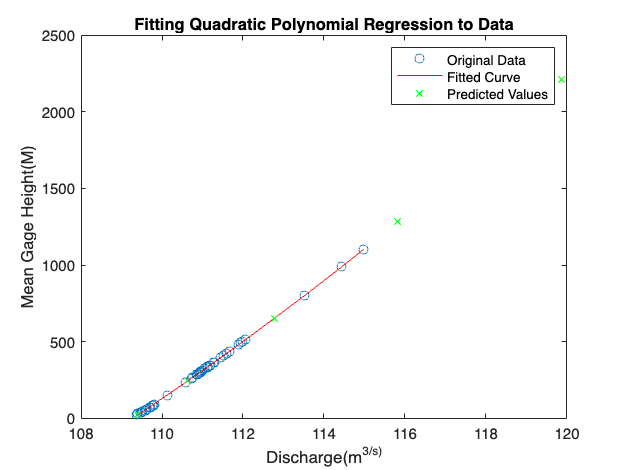


% Use the trained neural network to predict new values
new_x = (61:65)';
predicted_y_new = net(new_x');
h61_65 = predicted_y_new;

% Plot the original data, predictions on the test set, and predictions on new values
figure;
plot(x, y,'o' ,'DisplayName', 'Original Data');
hold on;
plot(testInputs, predicted_y_test, 'rx', 'DisplayName', 'Test Set Predictions');
plot(new_x, predicted_y_new, 'gx', 'DisplayName', 'New Values Predictions');
hold off;
legend('show');
xlabel('Days');
ylabel('Mean Gage Height (M)');
title('Neural Network Predictions');

คำนวณค่า Q D61-65 ของสถานี S1

% Read data from Excel file
xdata = readmatrix("dataset-2a.xlsx", 'Sheet', 'Q1A');
ydata = readmatrix("dataset-2a.xlsx", 'Sheet', 'Q1A');

% Flatten and clean x_data
xdata = xdata(:, 3);
%clr_x = rmmissing(xdata(:));
clr_x = qs1;

% Flatten and clean y_data
ydata = ydata(:, 2);
%clr_y = rmmissing(ydata(:));
clr_y = hs1;

% Data
y = clr_x;
x = clr_y;

% Fit quadratic polynomial regression model
polyModel = fitlm(x, y, 'poly2');

% Display the coefficients
coefficients = polyModel.Coefficients.Estimate;
intercept = coefficients(1);
linear_coeff = coefficients(2);
quadratic_coeff = coefficients(3);

fprintf('Fitted coefficients: intercept = %.4f, linear_coeff = %.4f, quadratic_coeff = %.4f\n', intercept, linear_coeff, quadratic_coeff);

Fitted coefficients: intercept = 18872.9194, linear_coeff = -520.3864, quadratic_coeff = 3.1816


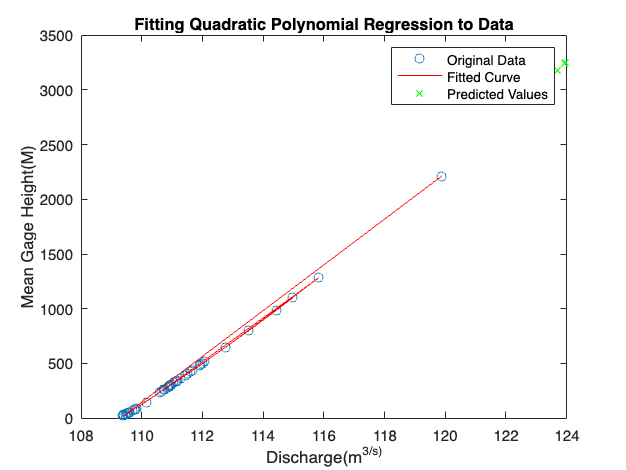


% Plot the original data, the fitted curve, and the predicted values
figure;
plot(x, y, 'o', 'DisplayName', 'Original Data');
hold on;
fittedCurve = intercept + linear_coeff * x + quadratic_coeff * x.^2;
plot(x, fittedCurve, 'r-', 'DisplayName', 'Fitted Curve');

% Input new values of x for prediction
new_y = h61_65';
predicted_x = predict(polyModel, new_y);
predicted_x = round(predicted_x, 2);
q61_65 = predicted_x;

% Plot the predicted values
plot(new_y, predicted_x, 'gx', 'DisplayName', 'Predicted Values');
hold off;

legend('show');
xlabel('Discharge(m^3/s)');
ylabel('Mean Gage Height(M)');
title('Fitting Quadratic Polynomial Regression to Data');


% Calculate R squared
R_squared = polyModel.Rsquared.Ordinary;

% Mean Absolute Error (MAE) calculation
MAE = mean(abs(y - fittedCurve));

% Mean Squared Error (MSE) calculation
MSE = sum((y - fittedCurve).^2)/numel(y);

fprintf('R squared: %.4f\n', R_squared);

R squared: 0.9999


fprintf('Mean Absolute Error (MAE): %.4f\n', MAE);

Mean Absolute Error (MAE): 1.6500


fprintf('Mean Squared Error (MSE): %.4f\n', MSE);

Mean Squared Error (MSE): 7.1284



% Display the predicted values
fprintf('Q61 - Q65: %.4f, %.4f, %.4f, %.4f, %.4f\n', predicted_x);

Q61 - Q65: 298.4500, 298.4500, 298.4500, 298.4500, 298.4500


Data Visualization

for i = 1:5
    fprintf('Day %d : H = %.4f, Q = %.4f\n', 60+i,h61_65(i),q61_65(i));
end

Day 61 : H = 110.9333, Q = 298.4500
Day 62 : H = 110.9333, Q = 298.4500
Day 63 : H = 110.9333, Q = 298.4500
Day 64 : H = 110.9333, Q = 298.4500
Day 65 : H = 110.9333, Q = 298.4500


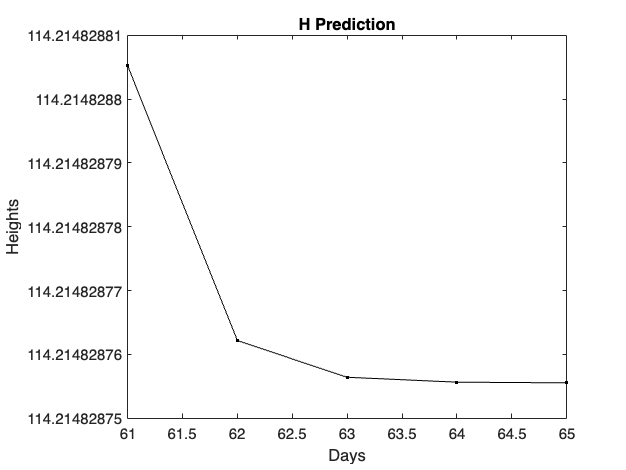


plot(61:1:65,h61_65,"-k.");
title("H Prediction");
xlabel("Days");
ylabel("Heights");

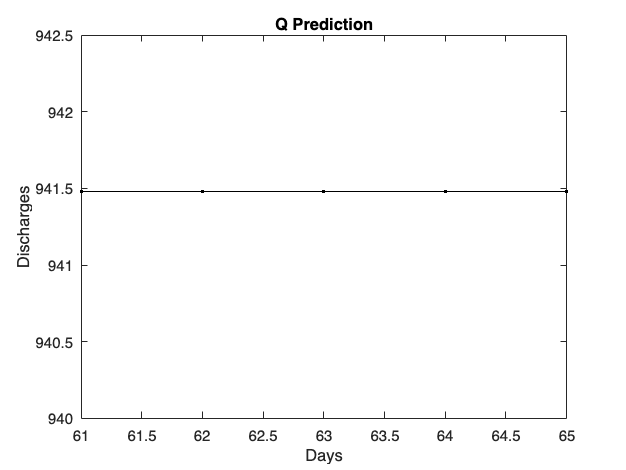


plot(61:1:65,q61_65,"-k.");
title("Q Prediction");
xlabel("Days");
ylabel("Discharges");

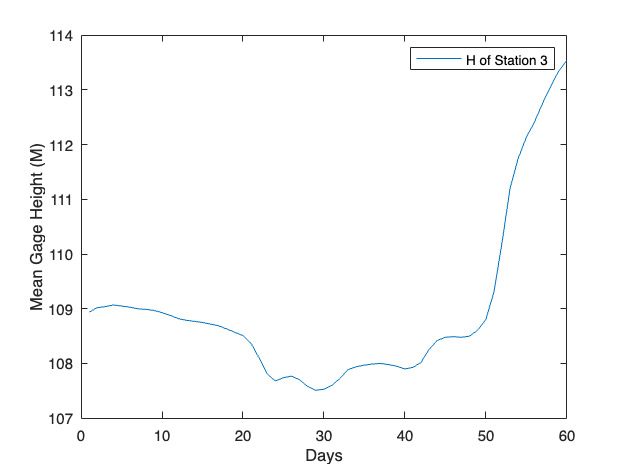


plot(1:60, hs3,'DisplayName', 'H of Station 3');
legend('show');
xlabel('Days');
ylabel('Mean Gage Height (M)');

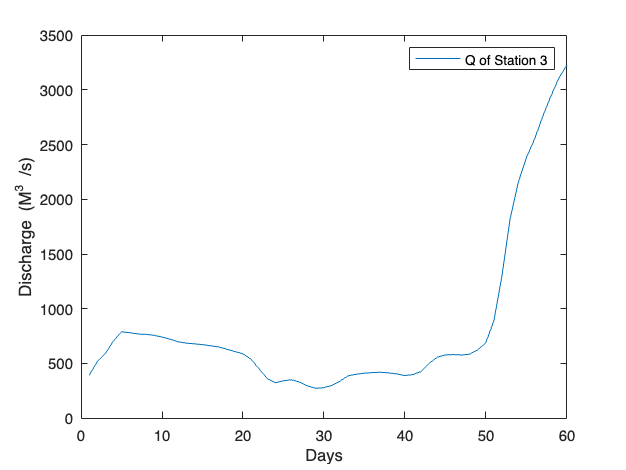


plot(1:60, qs3,'DisplayName', 'Q of Station 3');
legend('show');
xlabel('Days');
ylabel('Discharge (M^3 /s)');